Load Original Image

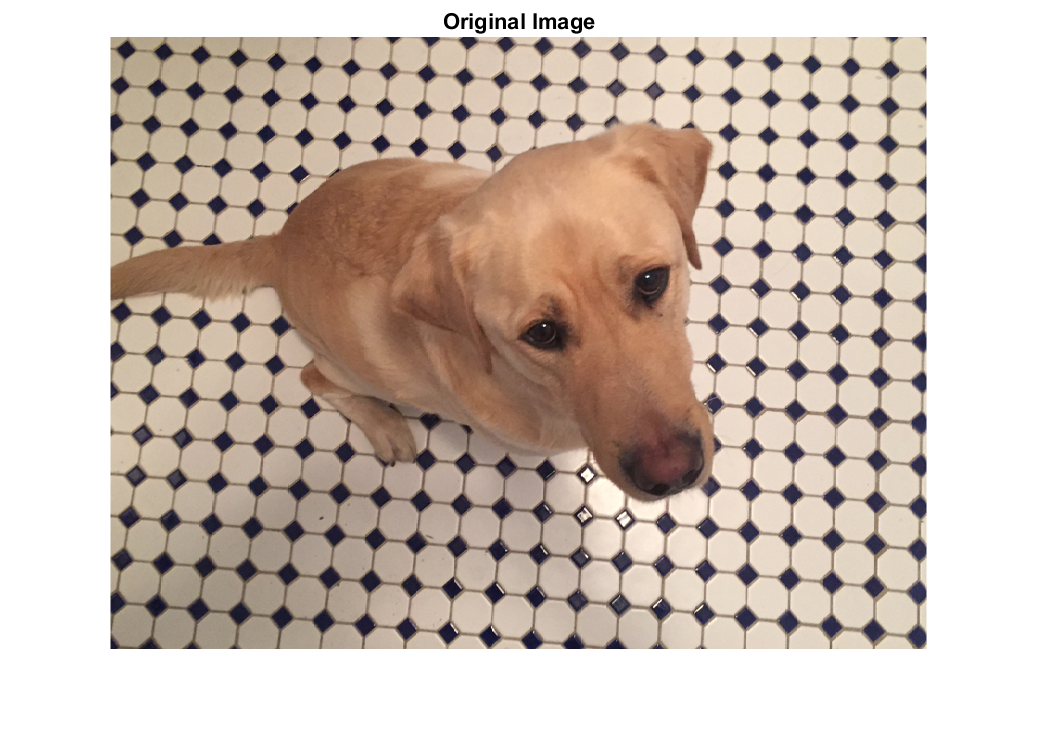

RGB = imread('kobi.png');
RGB = imresize(RGB,0.5);
figure
imshow(RGB)
title('Original Image');

Image segmentation using  K-nearest neighbors

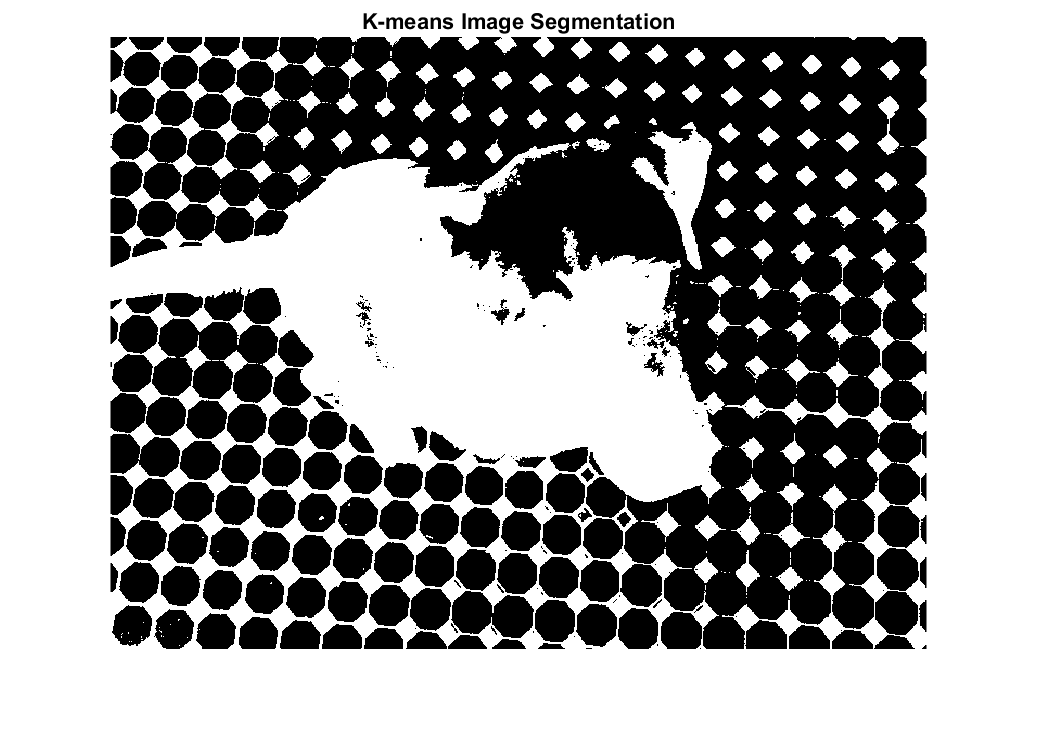

img_db = im2double(RGB);
vctr_img = imstack2vectors(img_db);
class_number = 2;
[kmeans_segmentation,c] = kmeans(vctr_img,class_number);
[width,height,bands] = size(img_db);
kmeans_segmentation = reshape(kmeans_segmentation,[width,height]);
figure;
imshow(kmeans_segmentation,[]);
title('K-means Image Segmentation');

Image segmentation using  Super Pixel 

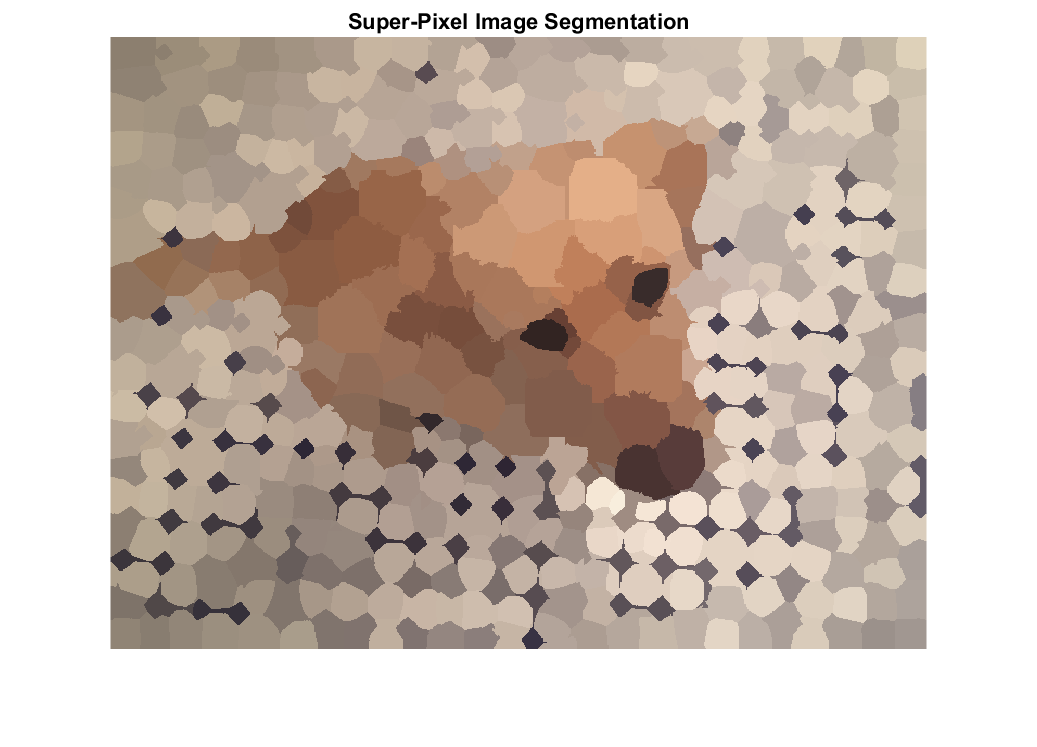

pixel_num = 500;
img_spr_pxl = spr_pxl_img(img_db,pixel_num);
figure;
imshow(img_spr_pxl);
title('Super-Pixel Image Segmentation');

Obtain the texture information, by filtering grayscale image with a set of Gabor filters.

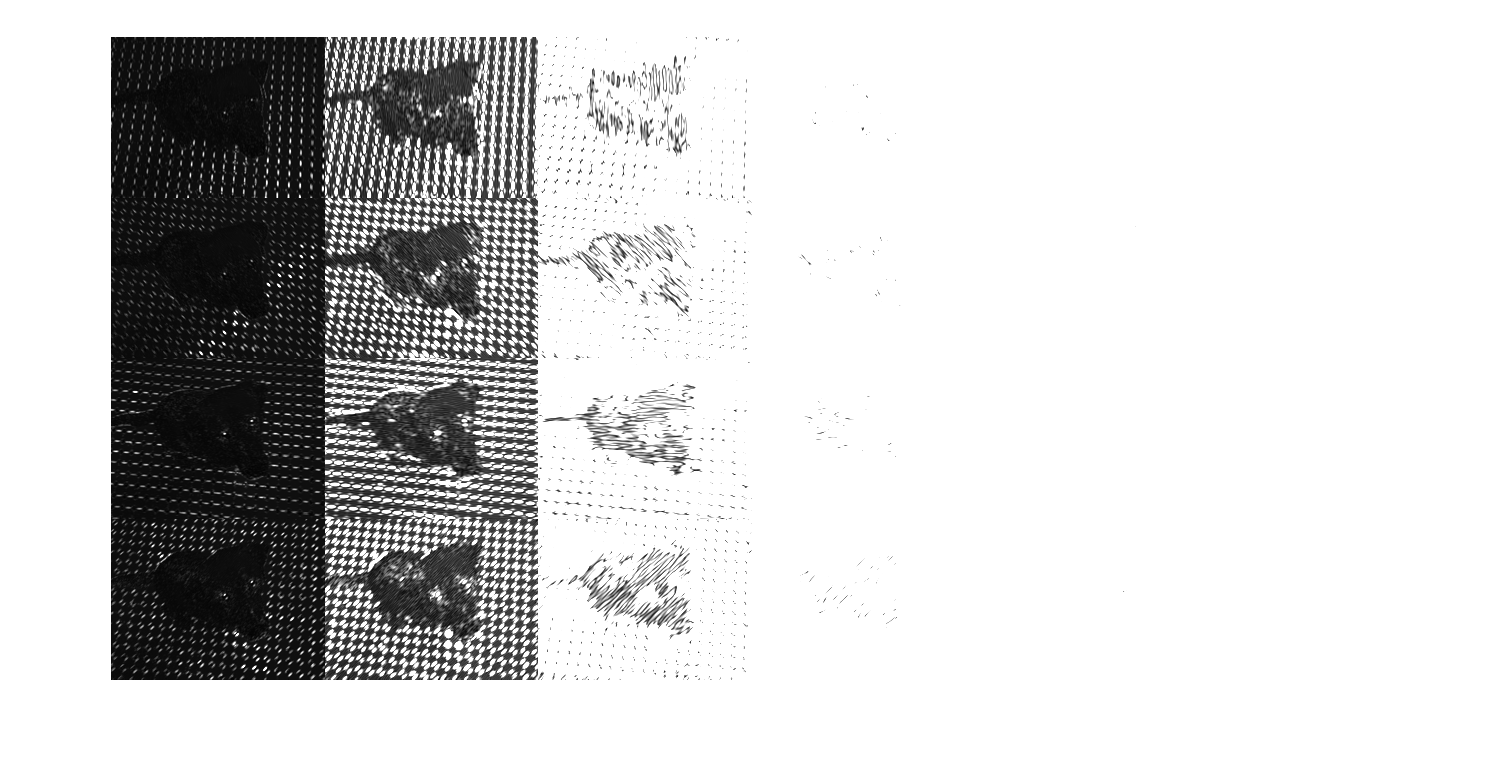

% Set of 24 Gabor filters, covering 6 wavelengths and 4 orientations.
wavelength = 2.^(0:5) * 3;
orientation = 0:45:135;
g = gabor(wavelength,orientation);
% Convert the image to grayscale.
I = rgb2gray(im2single(RGB));
% Filter the grayscale image using the Gabor filters. 
gabormag = imgaborfilt(I,g);
% Display the 24 filtered images in a montage.
figure
montage(gabormag,'Size',[4 6])

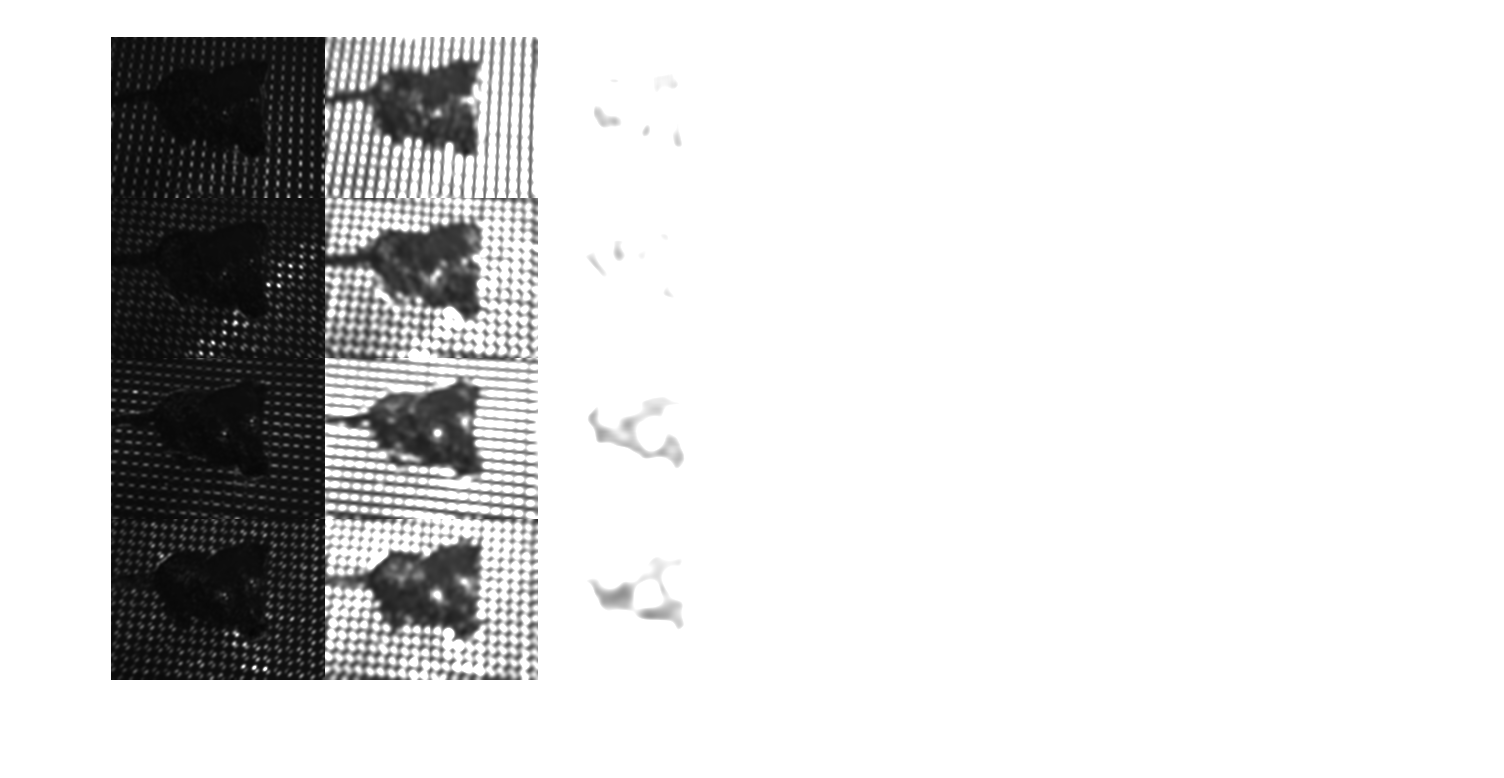

% Smooth each filtered image to remove local variations. 
for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),3*sigma); 
end
% Display the smoothed images in a montage.
figure
montage(gabormag,'Size',[4 6])

 Spatial location information

nrows = size(RGB,1);
ncols = size(RGB,2);
% Get the pixel-positions of input image.
[X,Y] = meshgrid(1:ncols,1:nrows);
% Concatenate the intensity information, 
% neighborhood texture information, and spatial information about each pixel.

Concatenate intensity information, neighborhood texture information, and spatial information about each pixel.

featureSet = cat(3,I,gabormag,X,Y);
% Segment the image into two regions (foreground - background)
% using k-means clustering with the supplemented feature set.
num_class = 2;
[L,C] = imsegkmeans(featureSet,num_class,'NormalizeInput',true);
RGBL = labeloverlay(RGB,L);

CRF model

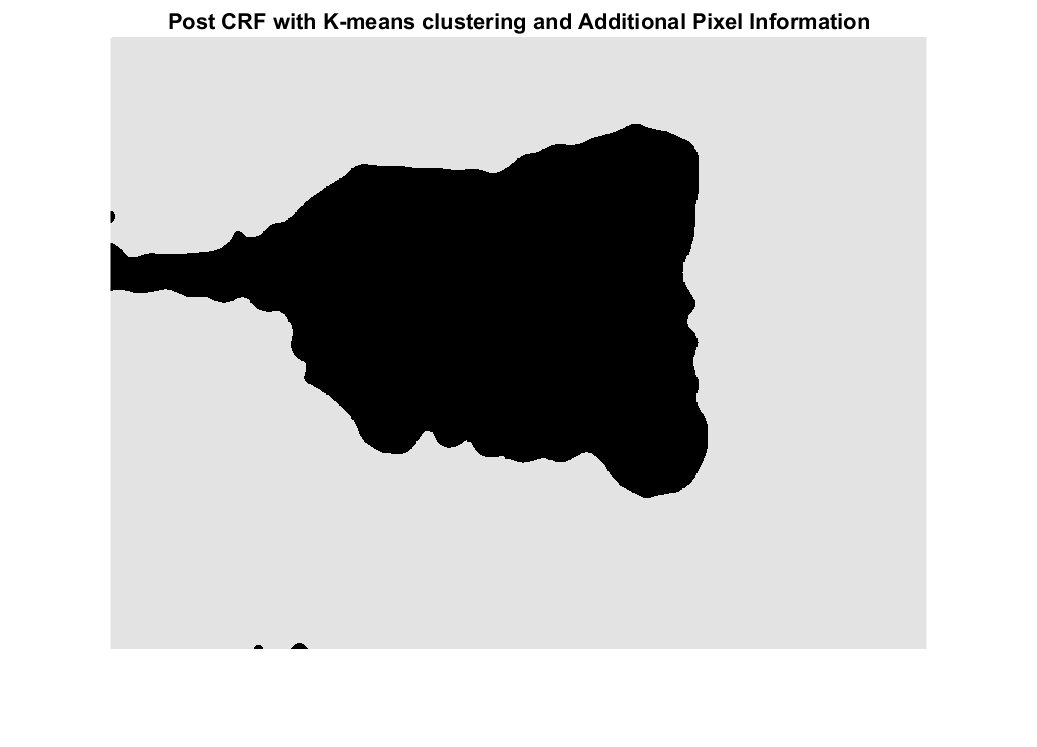

% get the neighbouring pixel positions
nx = NeiX(X);
ny = NeiX(Y);
% get the neighbouring intensity values
ni = NeiX(I);
% positions X,Y - coordinates
pos = cat(3,X,Y);
npos = cat(3,nx,ny);
% kmeans segmentation output
seg = double(L); 
% get the neighbouring segmentation values
prev_seg = NeiX(seg);
% label compatibility function
mu_lbl = ~(seg == prev_seg);
% label assignment probability 
prob_mtrx = zeros(size(seg));
for i = 1:num_class
    den = sum(seg(:) == i);
    prob_mtrx = prob_mtrx + (seg.*(seg == i))./den;
end
% unary potential energy
unry_enrgy = -log(prob_mtrx);
% gaussian kernel weightage
w1 = 3;
w2 = 1;
% gaussian kernel for pixel positions 
% and intensities combined
if(size(I,3) == 3)
    pw = w1*(exp(-(vecnorm((pos-npos),2,3)).^2) + exp(-sum((I-ni).^2,3)));
else
    pw = w2*(exp(-(vecnorm((pos-npos),2,3)).^2));
end
pair_enrgy =  mu_lbl.*pw;
% total - energy
E = unry_enrgy + pair_enrgy;
figure
imshow(E,[])
title('Post CRF with K-means clustering and Additional Pixel Information')

Stack image to vectors

function [X, R] = imstack2vectors(S, MASK)
[M, N, n] = size(S);
if nargin == 1
   MASK = true(M, N);
else
   MASK = MASK ~= 0;
end

[I, J] = find(MASK);
R = [I, J];

Q = M*N;
X = reshape(S, Q, n);

MASK = reshape(MASK, Q, 1);

X = X(MASK, :);
end

Mapping image to super pixel image 

function spr_pxl_img = spr_pxl_img(img,N)
[L,N] = superpixels(img,N);
outputImage = zeros(size(img),'like',img);
idx = label2idx(L);
numRows = size(img,1);
numCols = size(img,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(img(redIdx));
    outputImage(greenIdx) = mean(img(greenIdx));
    outputImage(blueIdx) = mean(img(blueIdx));
end    
spr_pxl_img = outputImage;
end